A = [-3, 0]'

A =     -3
     0


B = [0.732, 1]'

B =     0.7320
    1.0000



Ax = A(1)

Ax = -3

Ay = A(2)

Ay = 0


Bx = B(1)

Bx = 0.7320

By = B(2)

By = 1


R = 2

R = 2


syms a b c real 
alpha = -a/2

$$alpha = -\frac{a}{2}$$

beta = -b/2

$$beta = -\frac{b}{2}$$


syms x y real
eq = x^2 + y^2 + a*x + b*y + c == 0

$$eq = x^{2}+a\,x+y^{2}+b\,y+c=0$$


eq_1 = Ax^2 + Ay^2 + a*Ax + b*Ay + c == 0

$$eq\_1 = c-3\,a+9=0$$

eq_2 = Bx^2 + By^2 + a*Bx + b*By + c == 0

$$eq\_2 = \frac{183\,a}{250}+b+c+\frac{95989}{62500}=0$$

eq_3 = alpha^2 + beta^2 - c == R^2

$$eq\_3 = \frac{a^{2}}{4}+\frac{b^{2}}{4}-c=4$$


sol = solve([eq_1, eq_2, eq_3], [a, b, c])

sol = struct with fields:
    a: [2×1 sym]
    b: [2×1 sym]
    c: [2×1 sym]


a_ = sol.a(1)

$$a\_ = \frac{567}{250}-\frac{\sqrt{62520525879}}{932989}$$

b_ = sol.b(1)

$$b\_ = \frac{933\,\sqrt{62520525879}}{233247250}-1$$

c_ = sol.c(1)

$$c\_ = -\frac{3\,\sqrt{62520525879}}{932989}-\frac{549}{250}$$


alpha = -a_/2

$$alpha = \frac{\sqrt{62520525879}}{1865978}-\frac{567}{500}$$

beta = -b_/2

$$beta = \frac{1}{2}-\frac{933\,\sqrt{62520525879}}{466494500}$$


R = eval(sqrt(alpha^2 + beta^2 - c_))

R = 2

center = eval([alpha, beta]')

center =    -1.0000
   -0.0001


circle = subs(eq, {a, b, c}, {a_, b_, c_})

$$circle = x^{2}+\left(\frac{567}{250}-\frac{\sqrt{62520525879}}{932989}\right)\,x+y^{2}+\left(\frac{933\,\sqrt{62520525879}}{233247250}-1\right)\,y-\frac{3\,\sqrt{62520525879}}{932989}-\frac{549}{250}=0$$

r = 2

r = 2

x = center(1)

x = -1.0000

y = center(2)

y = -8.7993e-05

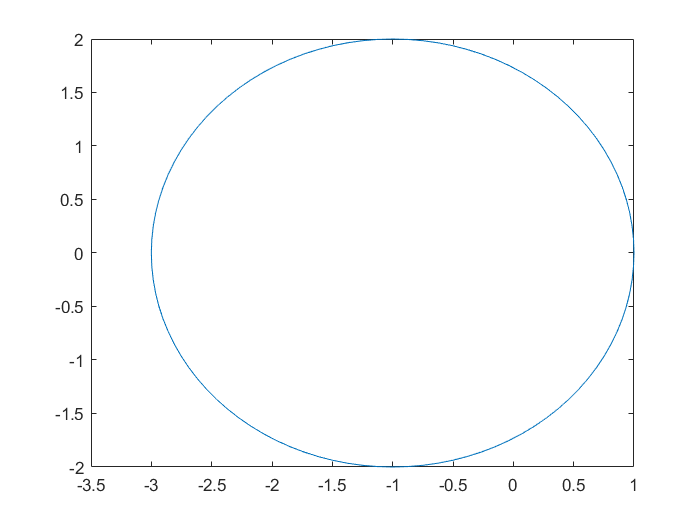

hold off


%hold on
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit);
hold off

C = [-1, 0]'

C =     -1
     0


R = 2

R = 2


angle_alpha = atan2(Ay - C(2), Ax - C(1))

angle_alpha = 3.1416

angle_beta = atan2(By - C(2), Bx - C(1))

angle_beta = 0.5236

gamma_b = angle_alpha-angle_beta

gamma_b = 2.6180


syms s real positive
p = C + R*[-cos(s/R), sin(s/R)]'

$$p = \left(\begin{array}{c} -2\,\cos\left(\frac{s}{2}\right)-1\\ 2\,\sin\left(\frac{s}{2}\right) \end{array}\right)$$


p_0 = eval(subs(p, {s}, {0}))

p_0 =     -3
     0


p_1 = eval(subs(p, {s}, {gamma_b*R}))

p_1 =     0.7320
    1.0000


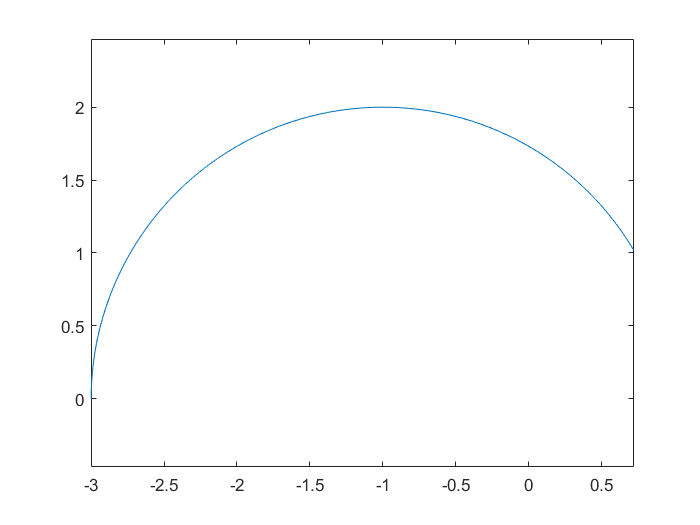

s_ = 0:pi/50:gamma_b*R; 
hold off
axis equal

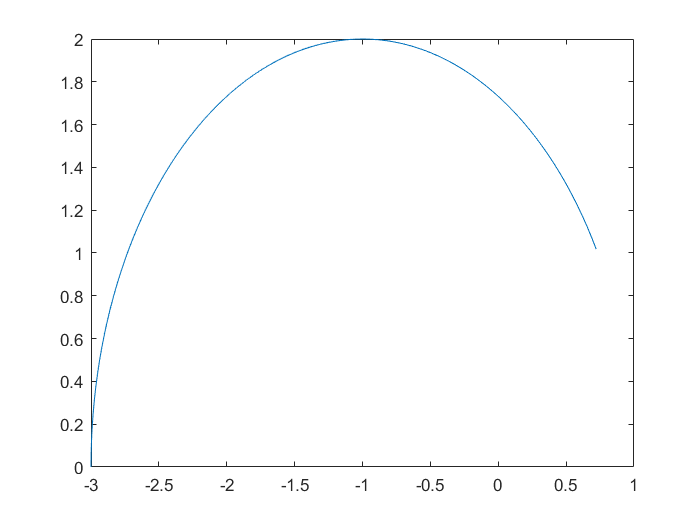

h = plot(subs(p(1), {s}, {s_}), subs(p(2), {s}, {s_}));

%hold off